# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 김동영**

**학번**** : 201710877**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 :  https://github.com/DongYeongKim123/DSP_HW_2.git**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

계산에 필요한 함수는 스크립트 끝에 정의해 두었습니다.

% 4점 DFT
xn = [1,2,2,1];
N = 4;
Xk = dft(xn,N);
Xk

Xk =    6.0000 + 0.0000i  -1.0000 - 1.0000i   0.0000 - 0.0000i  -1.0000 + 1.0000i



% 4점 IDFT
N = 4;
xn = idft(Xk,N);
xn

xn =    1.0000 - 0.0000i   2.0000 - 0.0000i   2.0000 + 0.0000i   1.0000 + 0.0000i


DTFT 값

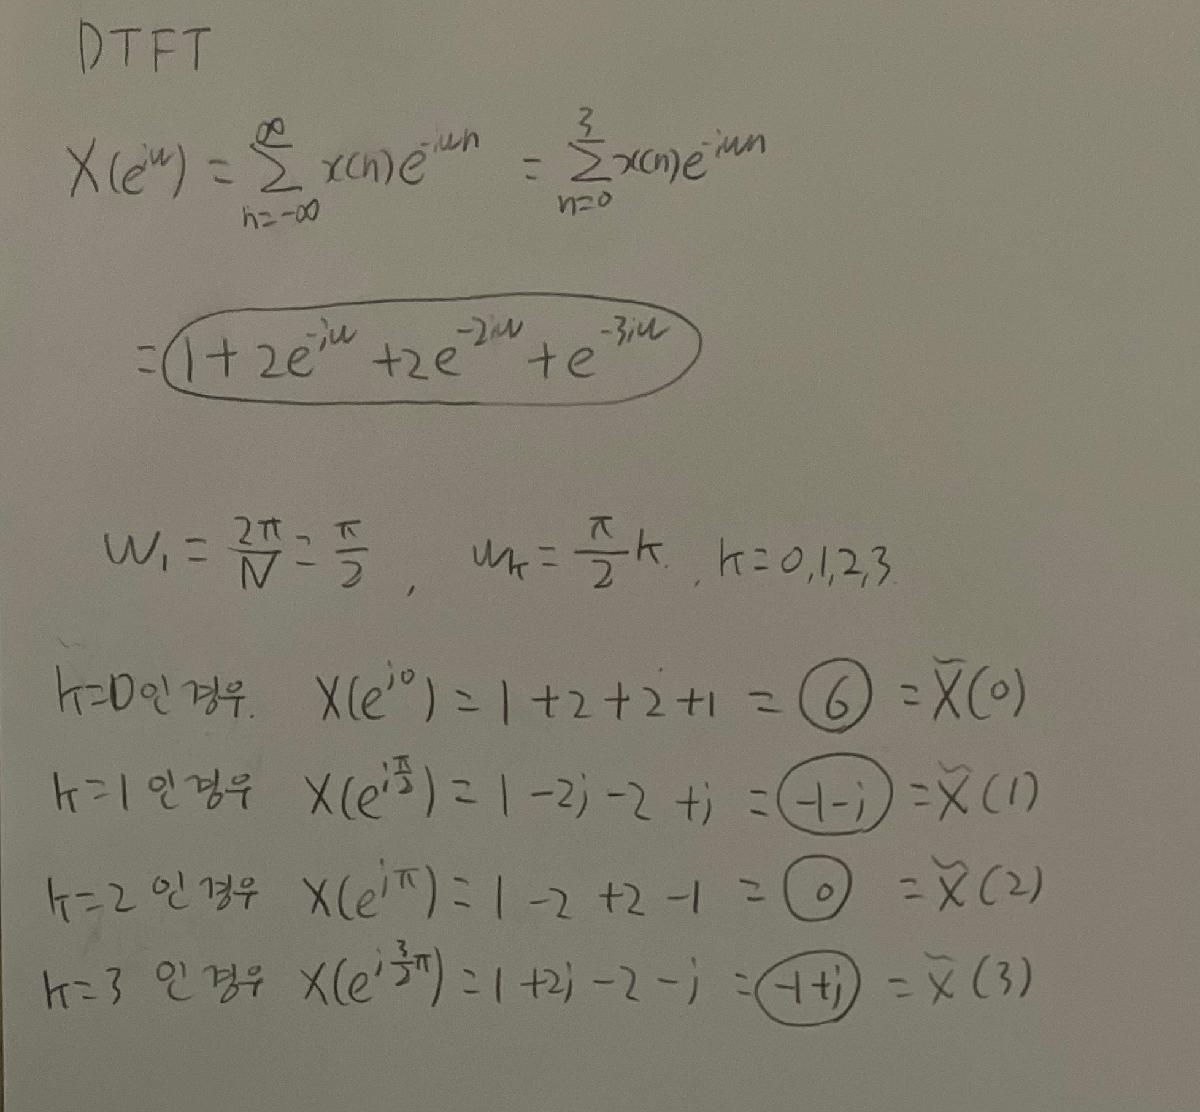

>>> 결과가 동일하다. 이는 2pi/N 의 샘플링 간격으로 DTFT를 균일하게 샘플링한 값임을 볼 수 있다.

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

% 16점 DFT
clear all;
xn = [1,2,2,1,zeros(1,12)];
N = 16;
Xk = dft(xn,N);
Xk

Xk =    6.0000 + 0.0000i   4.6447 - 3.1035i   1.7071 - 4.1213i  -0.5727 - 2.8793i  -1.0000 - 1.0000i  -0.2557 - 0.0509i   0.2929 - 0.1213i   0.1838 - 0.2750i   0.0000 + 0.0000i   0.1838 + 0.2750i   0.2929 + 0.1213i  -0.2557 + 0.0509i  -1.0000 + 1.0000i  -0.5727 + 2.8793i   1.7071 + 4.1213i   4.6447 + 3.1035i



% 16점 IDFT
N = 16;
xn = idft(Xk,N);
xn

xn =    1.0000 + 0.0000i   2.0000 + 0.0000i   2.0000 - 0.0000i   1.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

DFS계수 구하기

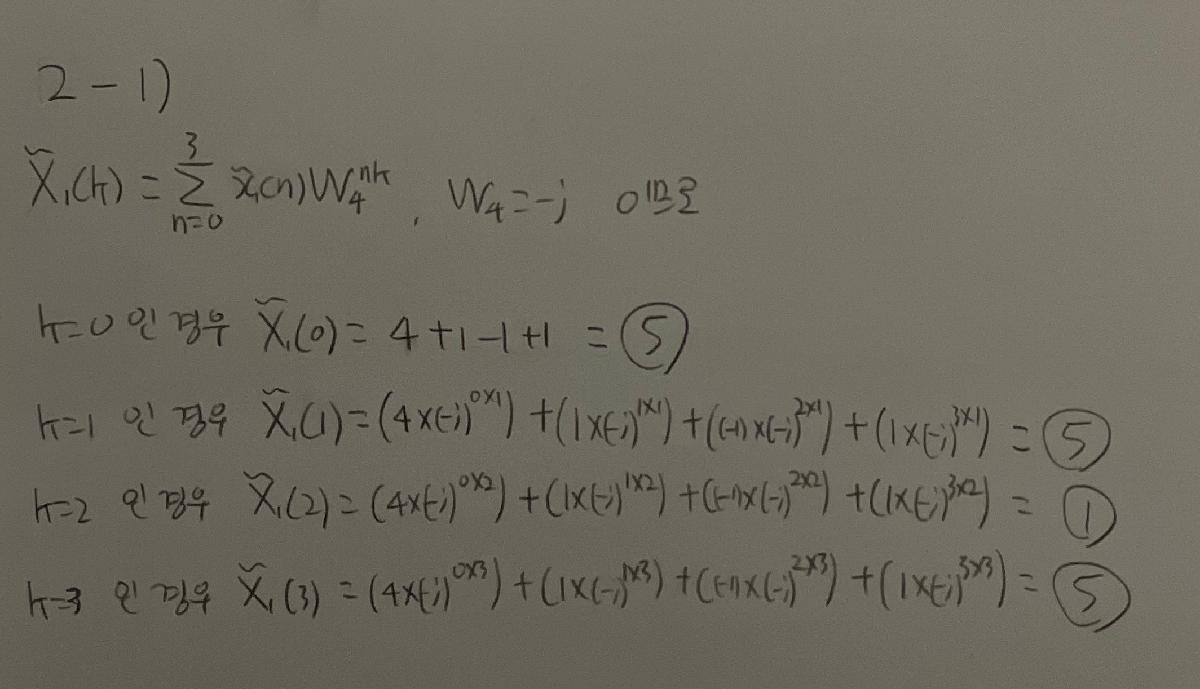

MATLAB 검증

clear all;
xn = [4,1,-1,1];
N = 4;
Xk = dfs(xn,N);
Xk

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


>>> 값이 동일하게 나왔음을 볼 수 있다.

2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

DFS 계수 구하기

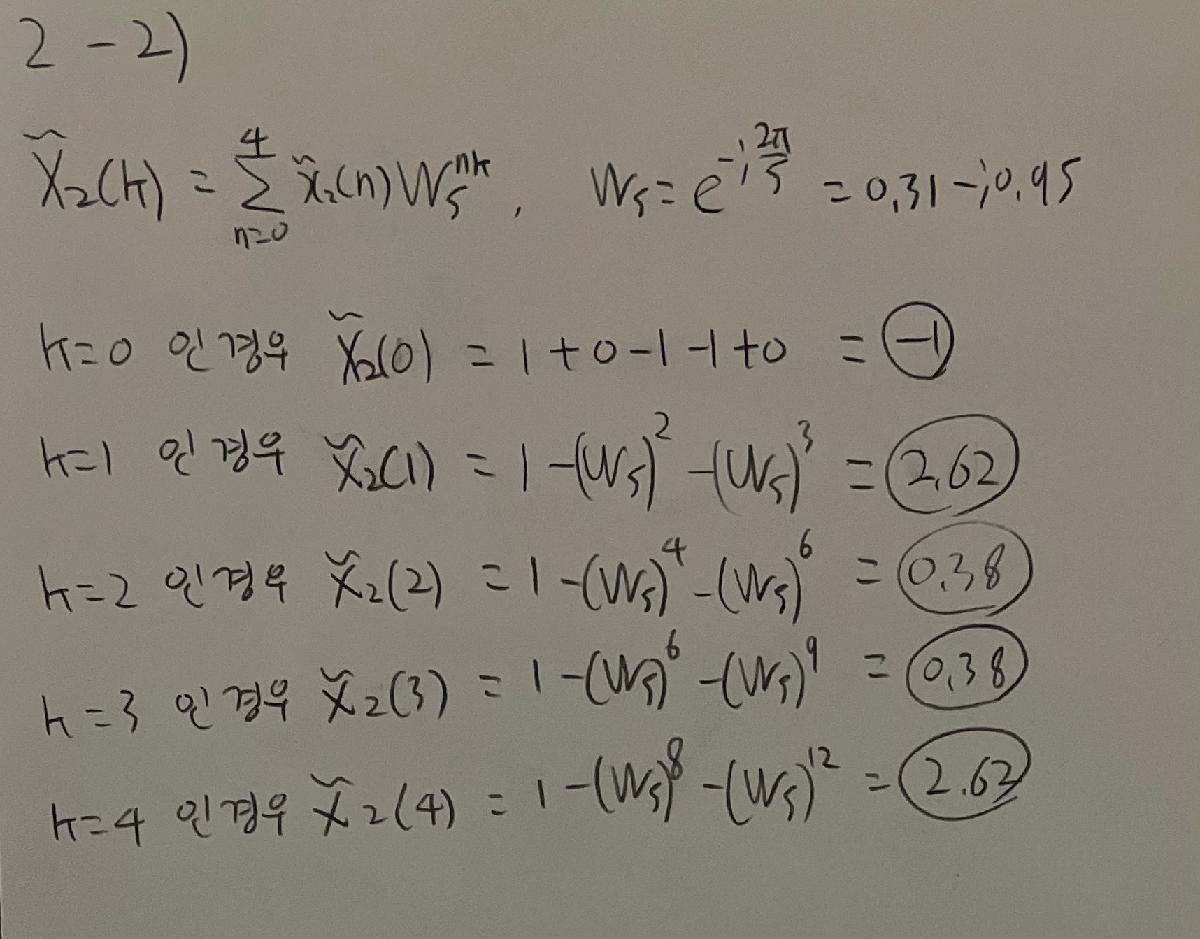

MATLAB 검증

clear all;
xn = [1,0,-1,-1,0];
N = 5;
Xk = dfs(xn,N);
Xk

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


>>>값이 동일하게 나왔음을 볼 수 있다.

3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

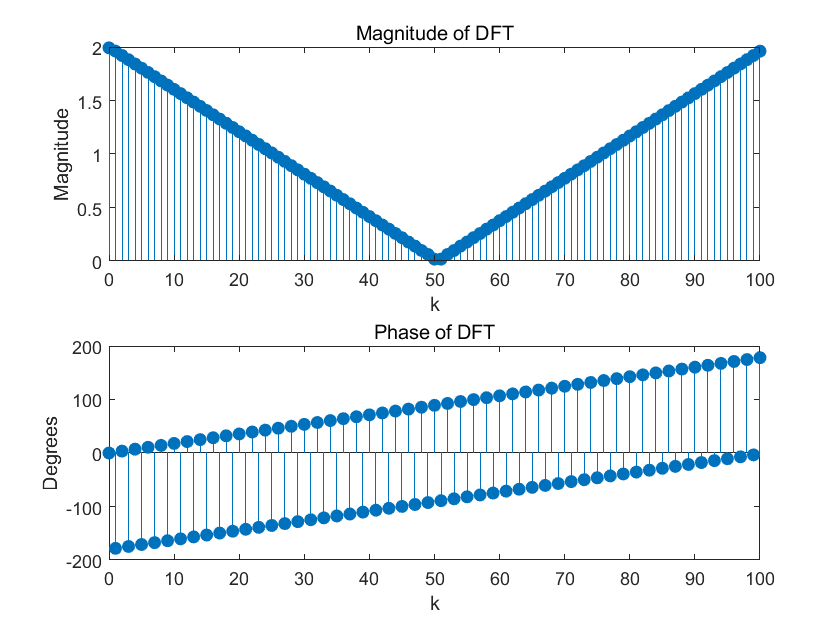

clear all;
n = 0:100; xn = sinc((n-50)/2).^2; N = length(xn); 
Xk = dft(xn,N); k = 0:N-1; 
mag_Xk = abs(Xk); pha_Xk = angle(Xk)*180/pi; 

figure ();
subplot(2,1,1);
stem(k,mag_Xk,'filled');
xlabel('k'); ylabel('Magnitude');
title('Magnitude of DFT'); hold on

subplot(2,1,2); 
stem(k,pha_Xk,'filled');
xlabel('k'); ylabel('Degrees');
title('Phase of DFT'); hold on

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

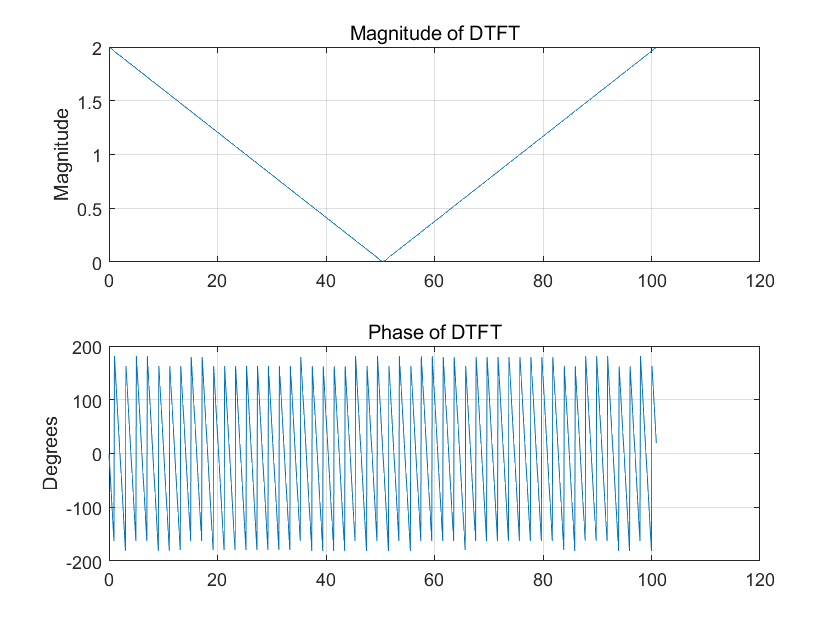

[X,w] = freqz(xn,1,1000,"whole"); 
mag_X = abs(X); pha_X = angle(X)*180/pi; 
Dw = (2*pi)/N; 

figure ();
subplot(2,1,1); plot(w/Dw,mag_X); grid
ylabel('Magnitude');
title('Magnitude of DTFT'); hold on

subplot(2,1,2); plot(w/Dw,pha_X); grid
ylabel('Degrees');
title('Phase of DTFT'); hold on

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

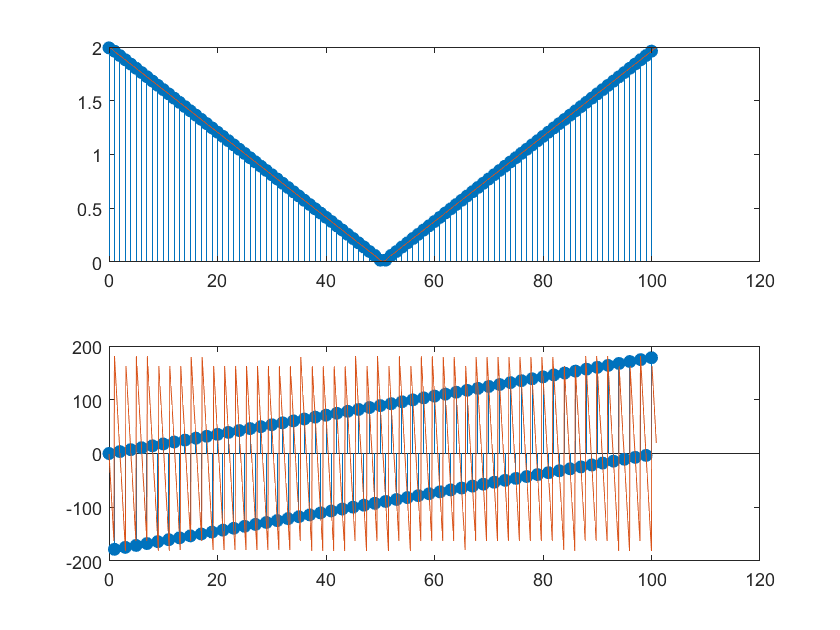

figure ();
subplot(2,1,1);
stem(k,mag_Xk,'filled'); hold on;

subplot(2,1,2); 
stem(k,pha_Xk,'filled'); hold on;

subplot(2,1,1); 
plot(w/Dw,mag_X); hold on;

subplot(2,1,2); 
plot(w/Dw,pha_X); hold on;

>>> 두 그래프를 합친 결과를 보면, 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 알 수 있다.

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

주파수영역의 샘플링 개수가 신호의 크기보다 크거나 같으면 재구성할 수 있다. 따라서 가능하다. 이를 계산해보면

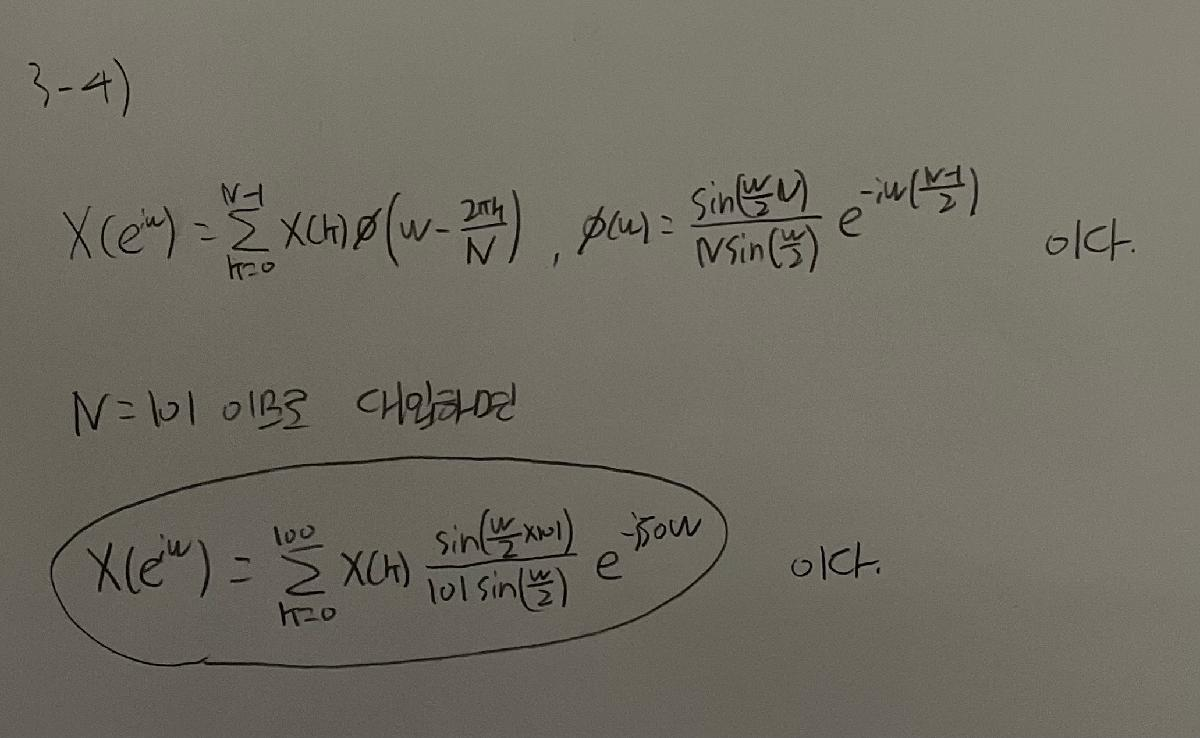

이 나온다.

함수 정의

function [Xk] = dft(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end


function [xn] = idft(Xk,N);
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end


function [Xk] = dfs(xn,N)
n = [0:1:N-1];
k = [0:1:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end